## Q3 -  Assignment modelling 

**(a) We analyse the parallel network with a single origin-destination pair and two links, shown above. Denote the link flows by x1, x2 ≥ 0 and prescribe total demand d, so that x1 + x2 = d. Per-user link costs c1(x1), c2(x2) are given by:**

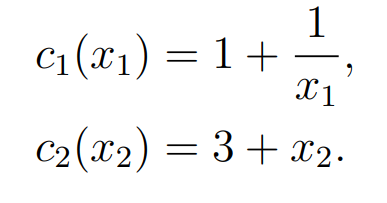

**Link 2 represents a standard congestible choice (e.g., car traffic) whose cost increases as it becomes more popular. However, link 1 represents a choice whose cost *****decreases***** as it becomes more popular — representing a public transport option where there is an economy of scale and more users enable a more frequent timetable and cheaper tickets. **

**(i) By considering link costs and a statement of Wardop’s equilibrium, demonstrate that x1 = 0 and x2 = d is a user equilibrium (UE) assignment, and derive a condition on d for which x1 = d and x2 = 0 is also a UE assignment. **

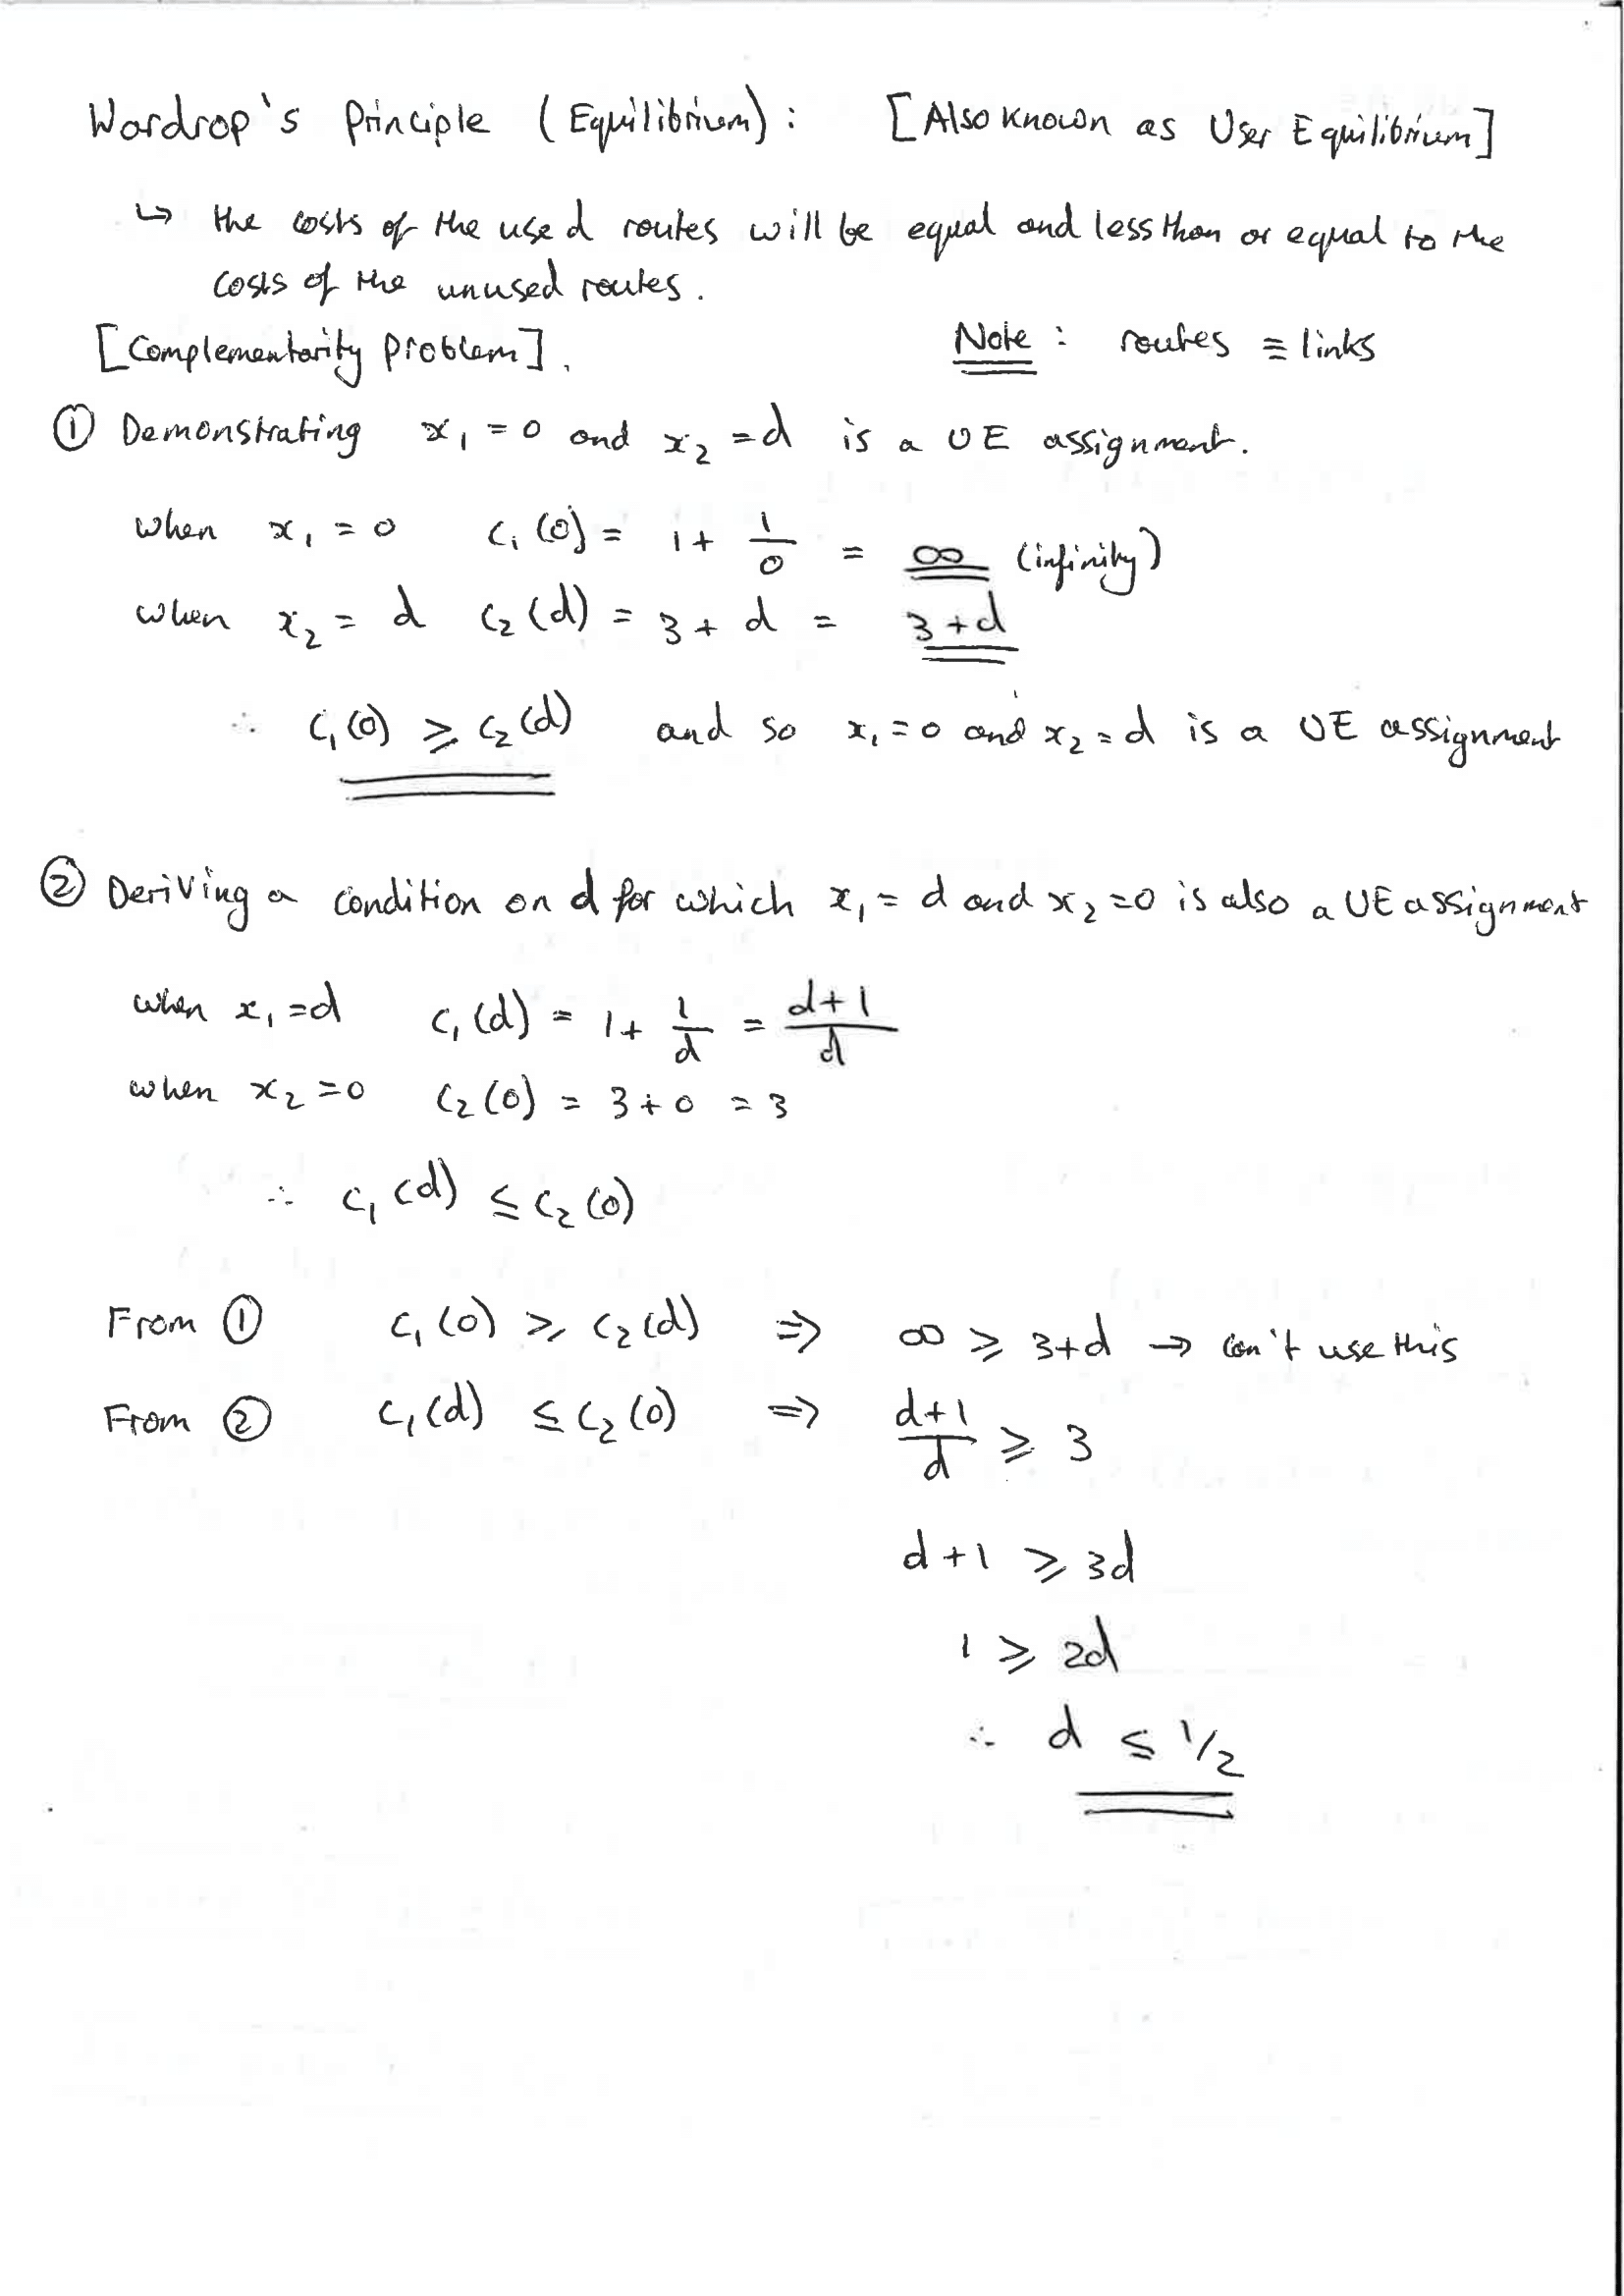

**(ii) Find an additional UE assignment where both links are used and their costs are equal, by solving an approriate quadratic for x1, and find the minimum demand d for which this assignment is valid (i.e., x1, x2 ≥ 0). **

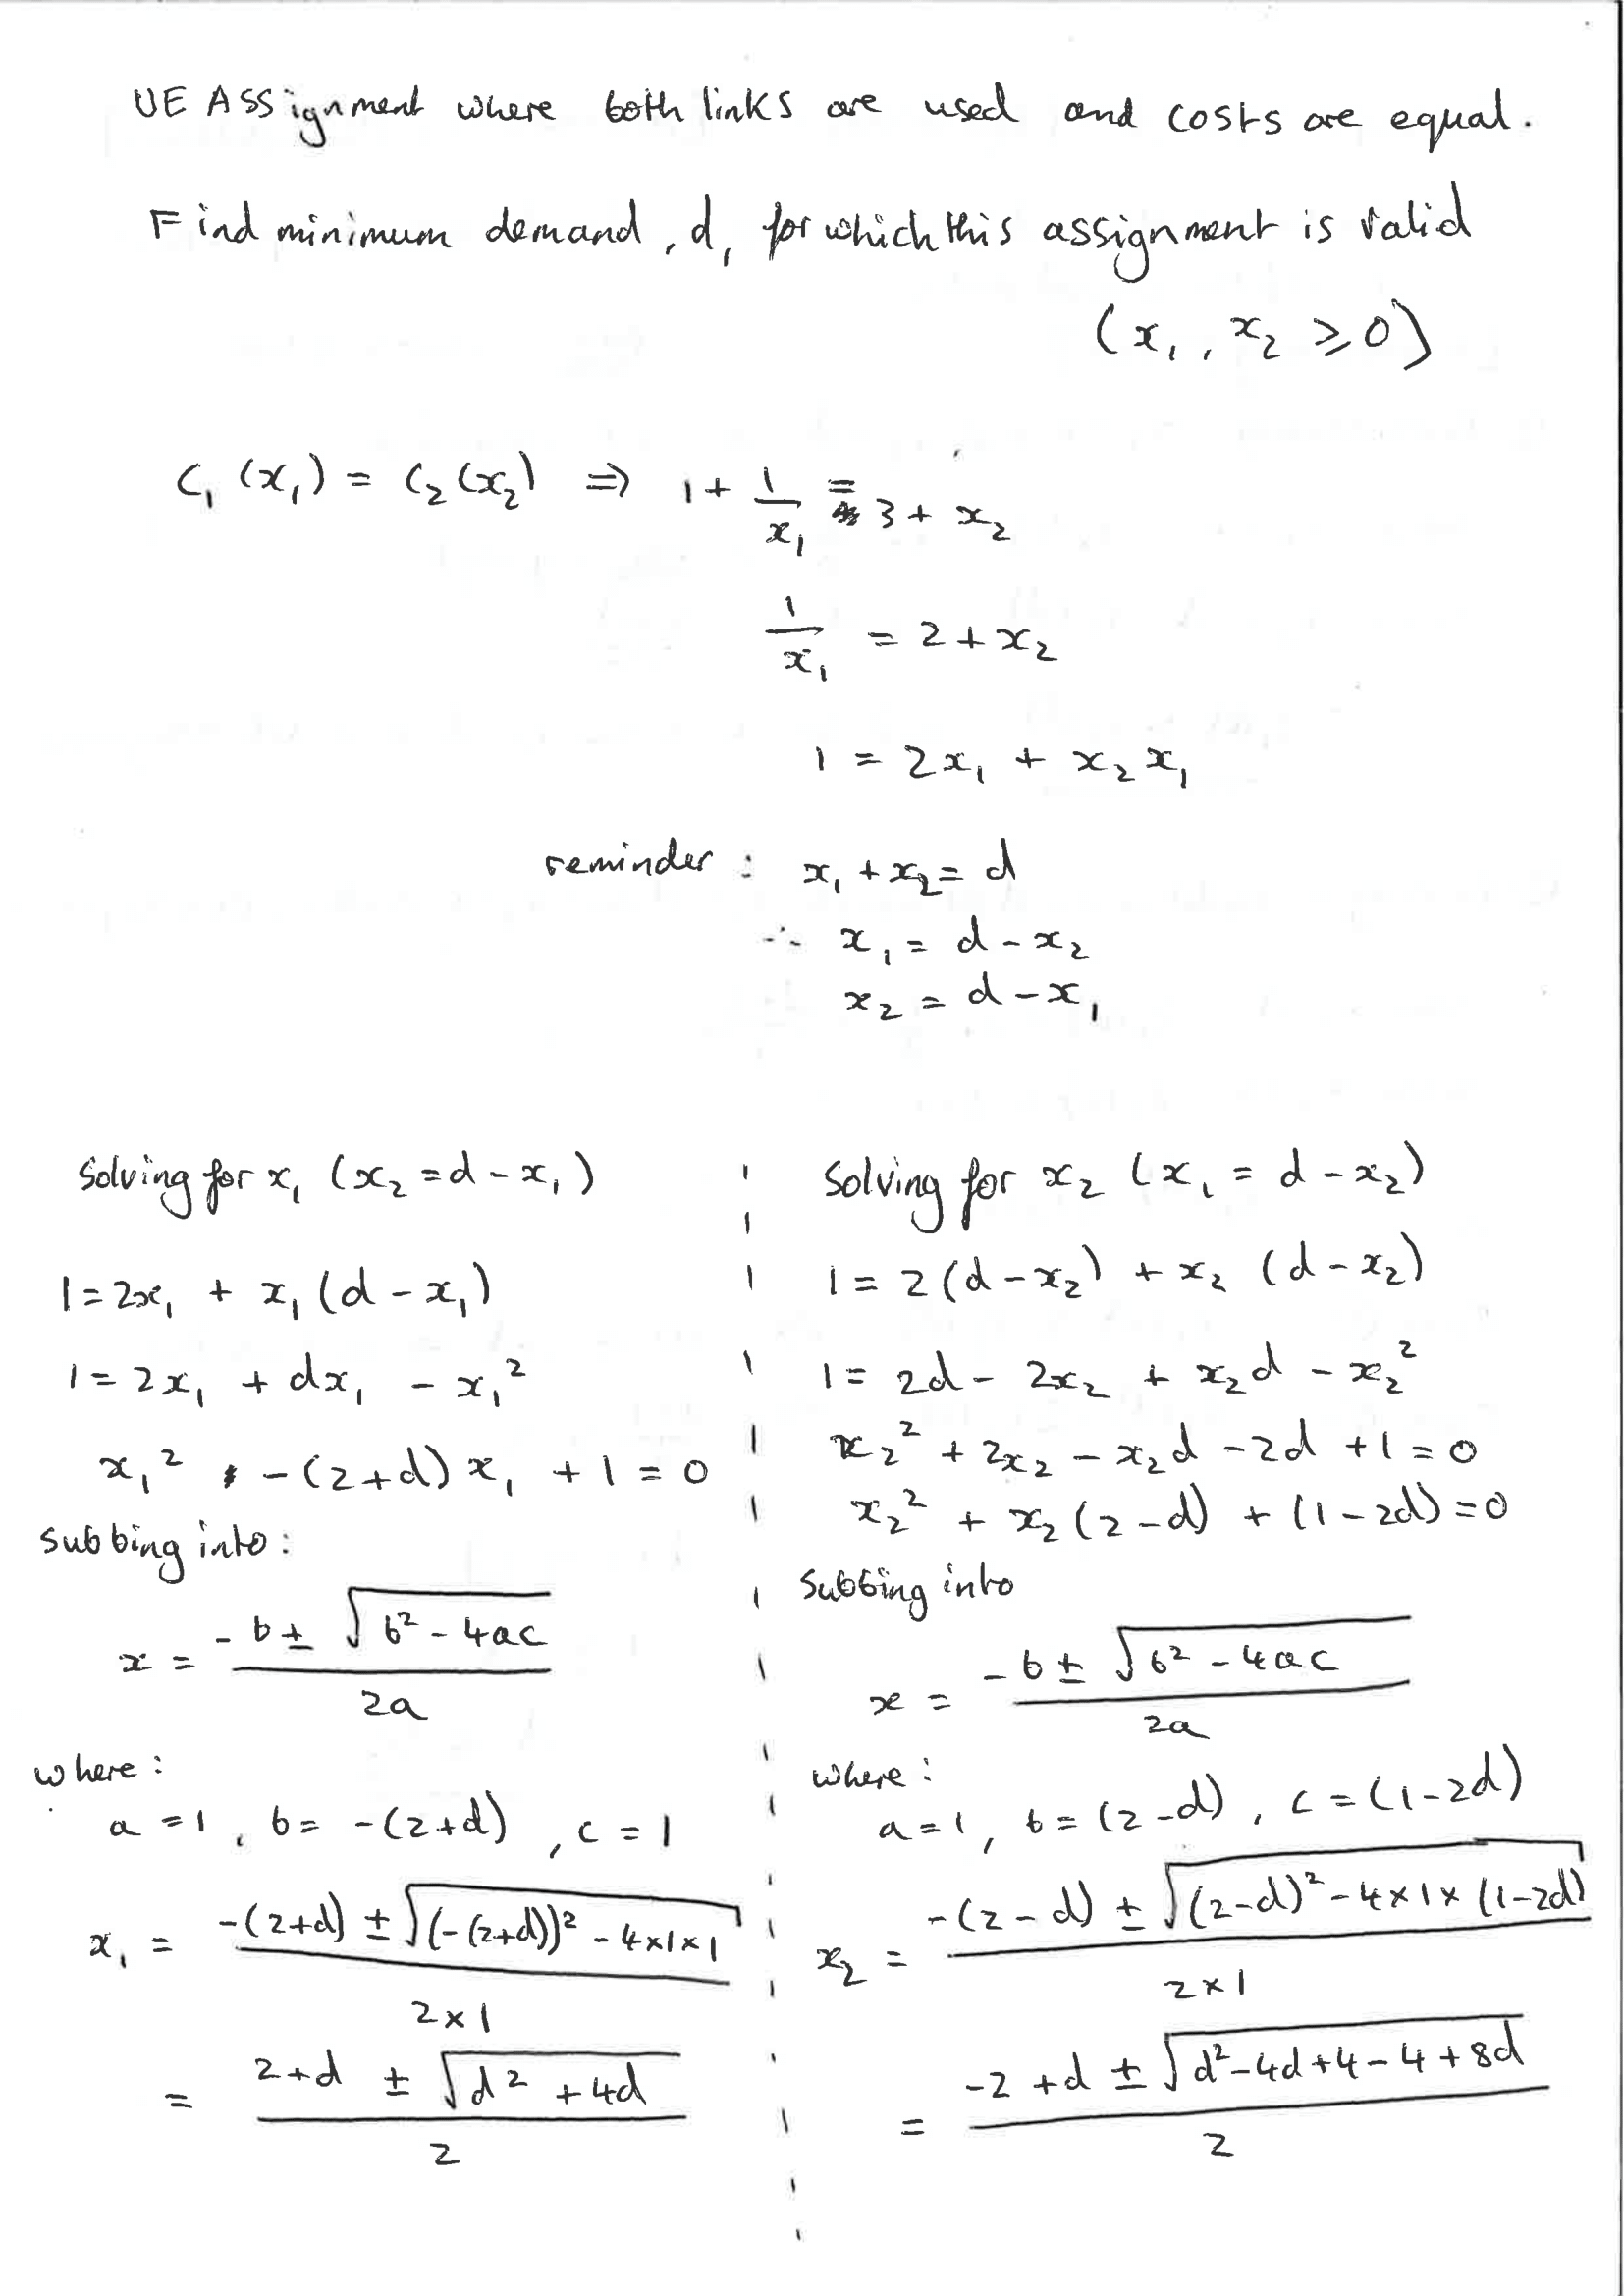

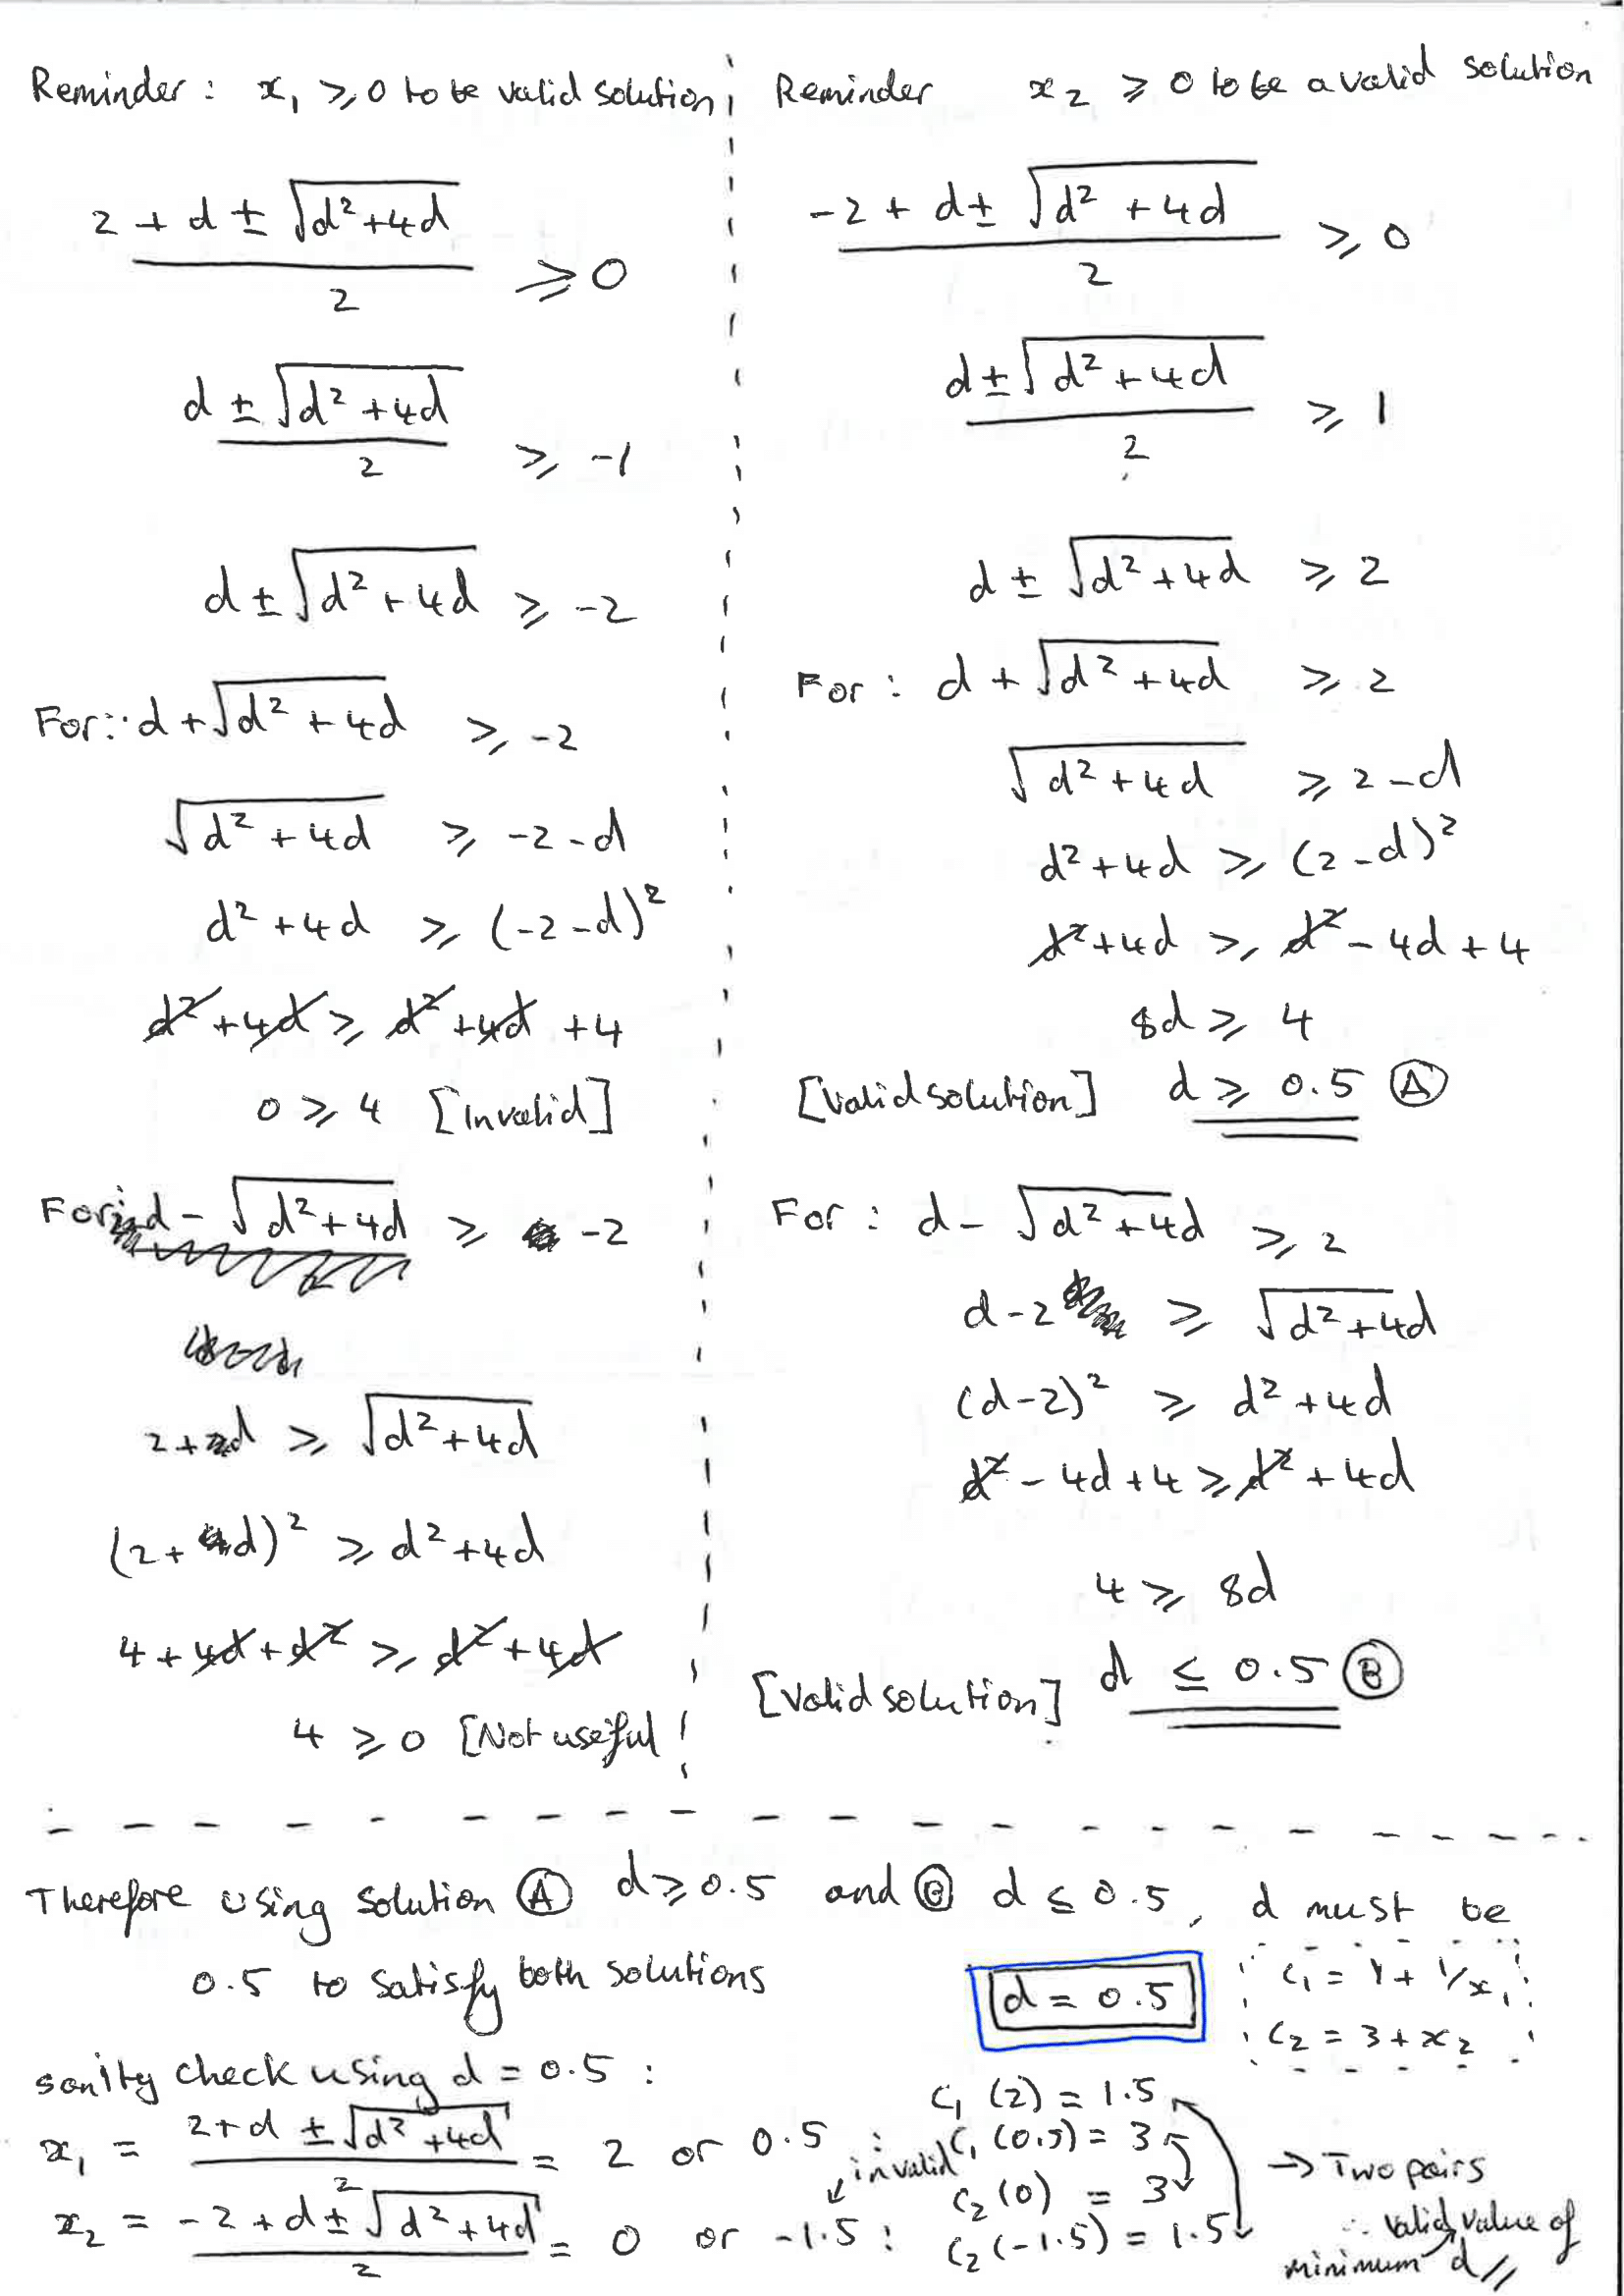

**(iii) Find the total system cost for the assignments you found in parts (i) and (ii) and discuss and interpret your results in terms of the suggested application setting.**

Discussion and interpretation of results

- Assignments 2 and 3 show the lowest total system cost of 1.5 while assignment 1 shows a higher total system cost of 1.75.

- Assignment 1 is the situation where all journeys are made with the standard congestible choice highlighting the inefficiency of individual traffic

- While assignment 2 is the situation where all journeys are made using public transport and shows a lower total system cost of 0.25, highlighting how when there is high demand the cost of mass-transport enables more frequent timetables and cheaper tickets that benefits most.

- Assignment 3 on the other hand, where both the cost of the use of standard congestible and public transport are equal shows the same total system cost to all journeys being made by public transport. This suggests the optimal combination of system to minimise cost for the majority is a mixture of standard congestible and public transport but with a heavier emphasis on the use of public transport to keep it economically efficient for all.

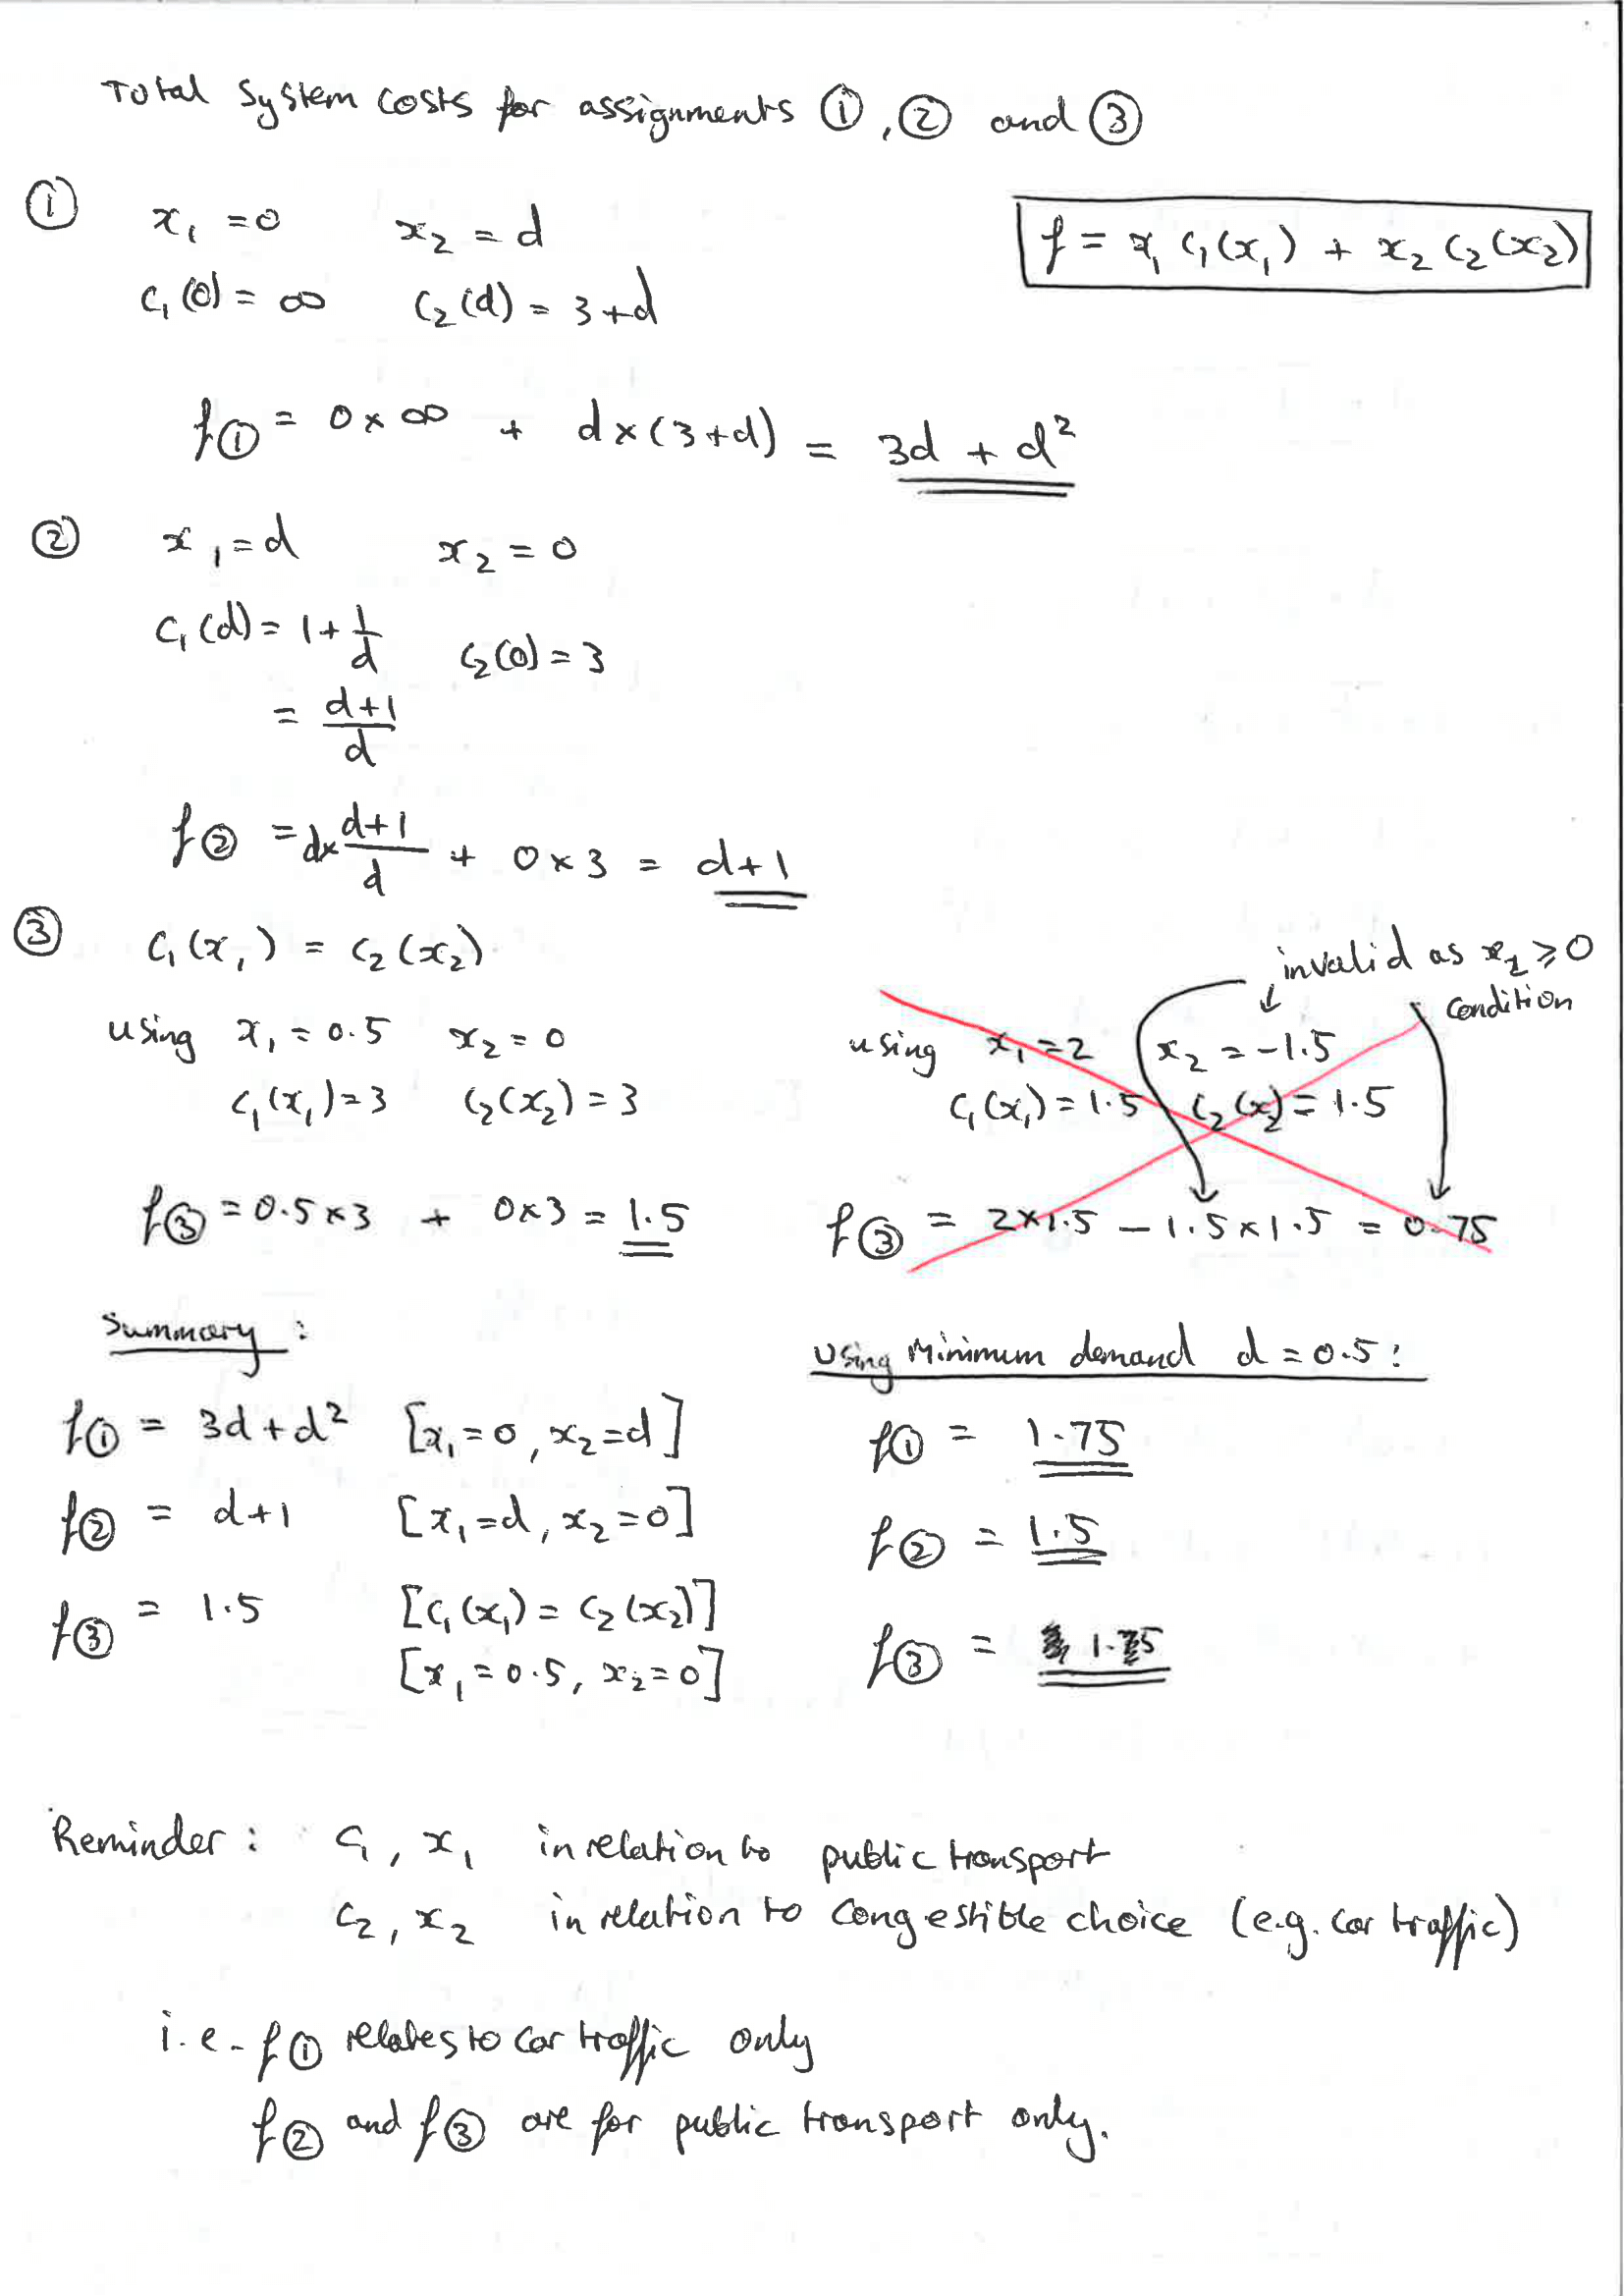

**(b) We are now going to compute UE for large networks. Study and adapt the provided livescript TMMcourseworkQ3.mlx which loads in the network provided in BigNetworkExperimentsBetaSkeleton.mat and formulates it so that quadprog can be used to solve the UE problem. **

**Show graphically how the network ‘fills up’ as demand d is increased from 0 over an appropriate range that you should choose. You should certainly ensure that the peak Price of Anarchy (PoA) is captured — and this may require you to also compute the System Optimal (SO) assignment. Finally, for the UE assignment with a fixed value of d that you should choose, demonstrate that there are multiple routes with the same total cost.**

I have done the following for this question:

- Studied and adapted the provided livescript. Plotted the network provided

- Set values of demand I believe to be good values.

- Solve the UE and SO problems for each value of demand, computing the system prices and PoA too.

- Plotted the values of fUE and fSO alongside PoA.

- Plotted the network and shown how it 'fills up' using coloured links.

- Demonstrated multiple routes have the same total cost for a fixed value of d=30 and plotted.

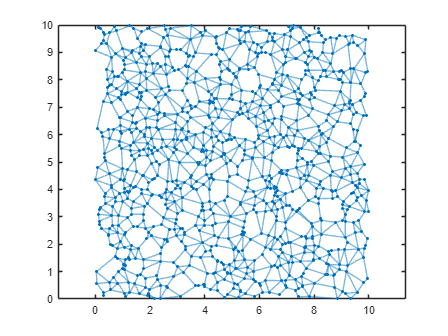

clear; close all
% Loading in required parameters
load BigNetworkExperimentsBetaSkeleton.mat

% Plotting the current graph (what is given in .mat file)
figure;
plot(G,'XData',nodeCoordinates(:,1),'YData',nodeCoordinates(:,2))%,'NodeLabelMode','auto')
axis([0 L 0 L])
axis equal

% Code provided
s = zeros(numNode,1);
s(oNode)=1;
s(dNode)=-1;

B=zeros(numNode,numEdge);
listEdge = 1:numEdge;
sNode = G.Edges.EndNodes(:,1);
tNode = G.Edges.EndNodes(:,2);

for i=1:numEdge
    B(sNode(i),listEdge(i))=1;
    B(tNode(i),listEdge(i))=-1;
end

Aeq=B;     % node conservation matrix
A=[];      % no inequality constraints
bvec=[];      % no inequality constraints - note avoiding name conflict with my existing b
LB = zeros(numEdge,1); % set a lower bound of zero for all of the link flows.
UB=[]; % no upper bounds for the link flows - although you could use this facility to set
% a capacity (ie max flow) for each link

H=diag(b); % the square matrix with the elements of b on its diagonal.
% Note this is what is needed for the Beckmann functional, because of the
% way matlab inserts a factor of 1/2 in front of the quadratic form.
% If we were doing SO, there would need to be a factor of 2 in here.

f=a; % the linear part of the quadratic form

% Setting the values of demand to iterate over and test
dvals = 1:1:30;

% Setting up the required UE storage arrays
xUE = zeros(length(dvals),numEdge);
fUE = zeros(length(dvals),1);
fUEperuser = zeros(length(dvals),1);

% Setting up the required SO storage arrays
xSO = zeros(length(dvals),numEdge);
fSO = zeros(length(dvals),1);
fSOperuser = zeros(length(dvals),1);

% Setting up the required PoA storage array
PoA = zeros(length(dvals),1);

% Index for each array corresponding to value of d
index = 1;

Ops = optimoptions("quadprog","Display","off");
for d = dvals
    beq=d*s;   % node conservation vector

    % Computing UE link flows for network provided
    [xUE(index,:),~]=quadprog(H,f,A,bvec,Aeq,beq,LB,UB,[],Ops);
    

    % compute total (system) cost
    fUE(index,:) = a'*xUE(index,:)' + xUE(index,:)*H*xUE(index,:)';
    % compute total (system) cost per user:
    fUEperuser(index) = fUE(index)/d;
    
    % Computing SO link flows for network provided
    % as for UE solution in route variables - but double the Hessian.
    [xSO(index,:),~]=quadprog(2*H,f,A,bvec,Aeq,beq,LB,UB,[],Ops);

    % compute total (system) cost
    fSO(index,:) = a'*xSO(index,:)' + xSO(index,:)*H*xSO(index,:)';
    % compute total (system) cost per user
    fSOperuser(index) = fSO(index,:)/d;
    
    % Compute price of anarchy using total system costs per user
    PoA(index) = (fUEperuser(index))/(fSOperuser(index));

    % For arrays to save numbers for each value of d correctly
    index = index + 1;
end

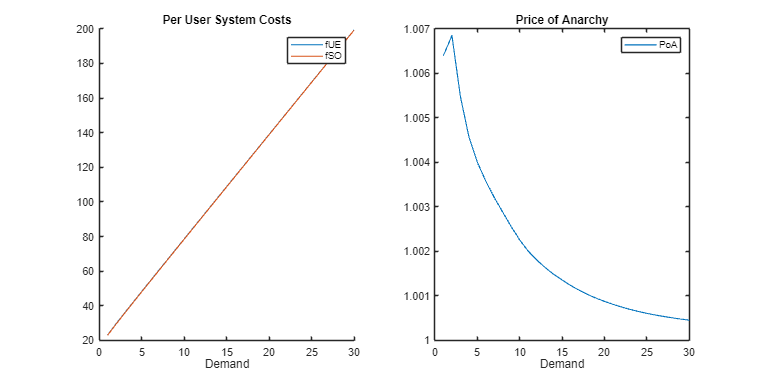

% Figure of per user system costs and PoA
figure;

% Plotting per user system costs
subplot(1,2,1)
hold on 
plot(dvals,fUEperuser,'LineWidth',1)
plot(dvals,fSOperuser,'LineWidth',1)
legend('fUE','fSO')
xlabel('Demand')
title('Per User System Costs')
hold off

% Plotting PoA
subplot(1,2,2)
plot(dvals,PoA,'LineWidth',1)
legend('PoA')
xlabel('Demand')
title('Price of Anarchy')

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,8])

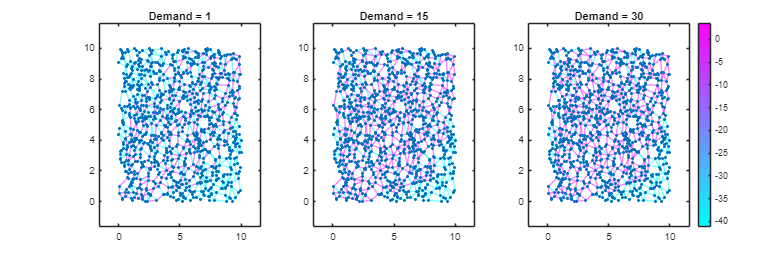

clf

% Detailing the network filling up as demand increases
figure;
tiledlayout(1,3)

% Plotting for first value of d
nexttile
p1 = plot(G,'XData',nodeCoordinates(:,1),'YData',nodeCoordinates(:,2));
% Setting title with correct d
title("Demand = "+string(dvals(1)))
% Colouring the edges using link flows
p1.EdgeCData = log(xUE(1,:)); % Using logs to show this more clearly

% Plotting for middle value of d
nexttile
p2 = plot(G,'XData',nodeCoordinates(:,1),'YData',nodeCoordinates(:,2));
% Setting title with correct d
title("Demand = "+string(dvals(15)))
% Colouring the edges using link flows
p2.EdgeCData = log(xUE(15,:)); % Using logs to show this more clearly

% Plotting for last value of d
nexttile
p3 = plot(G,'XData',nodeCoordinates(:,1),'YData',nodeCoordinates(:,2));
% Setting title with correct d
title("Demand = "+string(dvals(30)))
% Colouring the edges using link flows
p3.EdgeCData = log(xUE(30,:)); % Using logs to show this more clearly

% Colourmap and colourbar
colormap(cool);
colorbar;

% Specifying figure size
set(gcf,'units','inches','position',[0,0,15,5])

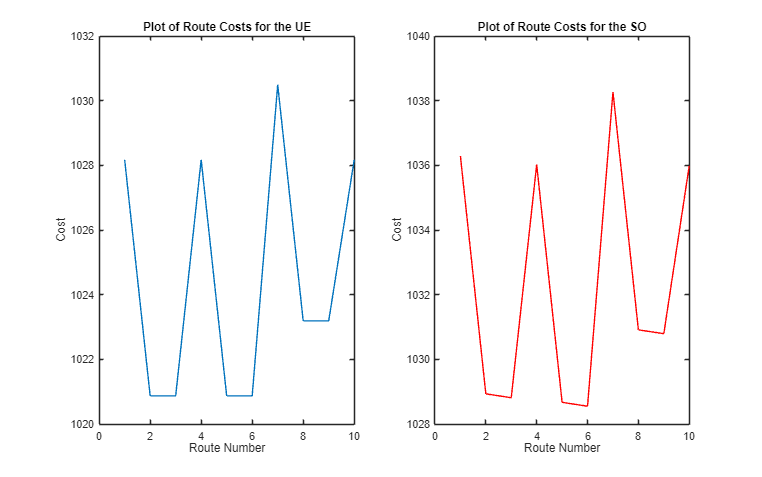

% Computing the route costs to show multiple routes have the same cost and
% plotting as a histogram for d = 3

% Obtaining 10 different paths
[nodepaths, edgepaths] = allpaths(G,oNode,dNode,'MaxNumPaths',10);

% compute link costs (could make an assumption routes=links???)
cUE = a + b.*xUE(30,:)';

% compute link costs
cSO = a + b.*xSO(30,:)';

% compute route costs
rUE = zeros(length(edgepaths),1);
rSO = zeros(length(edgepaths),1);

% Computing route costs
for i=1:length(edgepaths)
    edges = edgepaths(i);
    for j=1:length(edges{1})
        rUE(i) = rUE(i) + cUE(edges{1}(j));
        rSO(i) = rSO(i) + cSO(edges{1}(j));
    end
end

% Showing mutliple routes have the same cost by plotting a line graph
figure;
subplot(1,2,1);
plot(rUE)
xlabel("Route Number")
ylabel("Cost")
title("Plot of Route Costs for the UE")

subplot(1,2,2);
plot(rSO,'Color','r')
xlabel("Route Number")
ylabel("Cost")
title("Plot of Route Costs for the SO")

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])